# Obtenção da função de transferência

porta = "COM3";
velocidadeComunicacao = 115200;
%velocidadeComunicacao = 74880;
sampleRate = 100;
Ts = 1/sampleRate;

#### Curva de reação

s = serialport(porta, velocidadeComunicacao);
readline(s);

iteracoes = 201;
dados = ([]);
duty = ([]);
delimiter = ",";

degrau = "100";
writeline(s,degrau);
flush(s);

for j = 1:iteracoes
    if j == ((iteracoes+1)/2)
        degrau = "138";
        writeline(s,degrau);
    end
    
    duty(j) = str2num(degrau);
    try
       dados(j,:) = str2num(readline(s));
    catch ME
       dados(j,:) = dados(j-1,:);
    end
    %dados(j,:) = split(readline(s),delimiter);
    
end

degrau = "0";
writeline(s,degrau);

clear s

#### Plotagem 

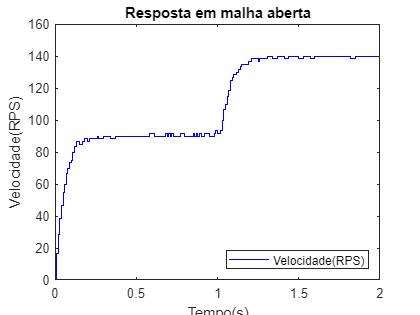

t = 0:1/sampleRate:length(dados)/sampleRate-1/sampleRate;

stairs(t,smooth(dados(:,2),3),"b");
title('Resposta em malha aberta')
xlabel('Tempo(s)')
ylabel('Velocidade(RPS)')
legend('Velocidade(RPS)', 'Location',"southeast")
ylim([0 160])

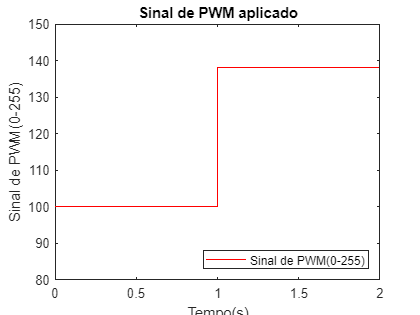



stairs(t,duty,'r')
title('Sinal de PWM aplicado')
xlabel('Tempo(s)')
ylabel('Sinal de PWM(0-255)')
legend('Sinal de PWM(0-255)', 'Location',"southeast")
ylim([80 150])

#### Curva de reação

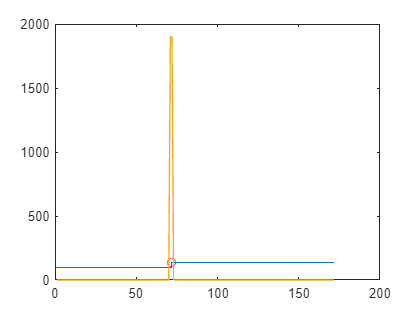

Ts = 1/sampleRate;

y = smooth(dados(30:end,2),3);
u = duty(30:end);
time = 0:Ts:length(y)*Ts-Ts;

d1 = [1 0 -1]/(Ts*2);

diff_u = conv(u,d1,'same');
diff_u(1) = 0;
diff_u(end) = 0;
[max_diff_u,id_0] = max(diff_u);
stairs(u)
hold on
id_0 = id_0 + 1;
plot (id_0,u(id_0), 'ro')
plot ( diff_u)
hold off

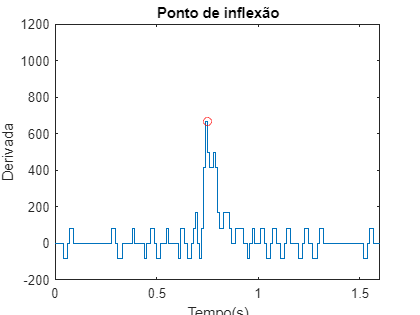


y_0 = mean(y(id_0-20:id_0));
y_inf = mean(y(end-20:end));
u_0 = u(1);
u_f = u(end);

k = (y_inf - y_0) / (u_f - u_0);

%derivada de primeira ordem
diff_y = conv(y,d1,'same');
diff_y(1) = 0;
diff_y(end) = 0;

[max_diff_y , id_max_diff_y] = max(diff_y);

stairs(time,diff_y);
hold on
plot (id_max_diff_y*Ts,max_diff_y, 'ro');
hold off
title('Ponto de inflexão')
xlabel('Tempo(s)')
ylabel('Derivada')
xlim([0 1.6])
ylim([-200 1200])

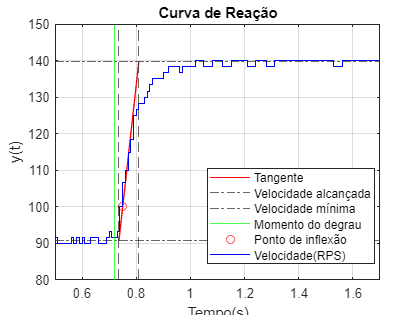


T = (y_inf-y_0)/max_diff_y;

x_0 = id_max_diff_y*Ts + (y_0 - y(id_max_diff_y))/max_diff_y;
x_1 = id_max_diff_y*Ts + (y_inf - y(id_max_diff_y))/max_diff_y;

L = x_0 - id_0*Ts;

plot([x_0 x_1], [y_0 y_inf],"r")
hold on
yline(y_inf,"-.")
yline(y_0,"-.")
xline(id_0*Ts,"g")
xline(x_0,"--")
xline(x_1,"--")
plot(id_max_diff_y*Ts,y(id_max_diff_y),"or")
stairs(time, y,"b")
hold off

grid on
title('Curva de Reação')
xlabel('Tempo(s)')
ylabel('y(t)')
xlim([0.5 1.7])
ylim([80 150])
legend("Tangente", "Velocidade alcançada", "Velocidade mínima", "Momento do degrau", "", "", "Ponto de inflexão", "Velocidade(RPS)", "Location","best")

#### Validação

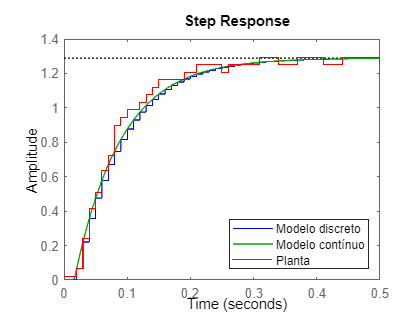

sys = tf([k],[T 1], "IODelay",L);
sysz = c2d(sys,Ts);
step(sysz,"b");
hold on
step(sys,"g");

title('Resposta ao degrau')
stairs(time(1:end-id_0+1),(y(id_0:end)-y_0)/(u_f - u_0),"r")
legend("Modelo discreto","Modelo contínuo", "Planta", "Location","southeast")
hold off

#### Salvando workspace

%save("modelo");